# **Portfolio Analysis: Backtesting and Performance Evaluation **

# Share Repurchase Announcements

### **Preliminaries**

%tic
clc;
clear;

### Data

opts = detectImportOptions('sample_buyback_portfolio_entropy.csv');
data = readtable('sample_buyback_portfolio_entropy.csv', opts);

### Index Variables

- Bibary Entropy:* 'H_quantile'*

- Binomial Entropy*: 'H2_quantile'*

- Self-Information Content:* 'I_quantile'*

- Cash*: 'cash_quantile'*

- IVOL: *'ivol_quantile'*

- Ownership:* 'ownership_quantile'*

- Payout: *'payout_quantile'*

- *Profitability: 'profitability_quantile'*

- *Momentum: 'momentum_quantile'*

IndexVariables = {'cash_quantile','ivol_quantile','momentum_quantile','profitability_quantile'};

### **Performance Evaluation Models**

- MKTRF       = Market Risk Premium

- SMB            = Size Factor

- HML            = Value Factor

- UMD            = Momentum Factor

- RMW           = Profitability Factor

- CMA            = Growth Factor

- LIQ              = Liquidity Factor

TopPerfModel = 'TopExcess~MKTRF+SMB+HML+RMW+CMA+UMD'%+LIQ';

TopPerfModel = 'TopExcess~MKTRF+SMB+HML+RMW+CMA+UMD'

BottomPerfModel = 'BottomExcess~MKTRF+SMB+HML+RMW+CMA+UMD'%+LIQ';

BottomPerfModel = 'BottomExcess~MKTRF+SMB+HML+RMW+CMA+UMD'

### Firm Size

- Full sample: "Full Sample"

- Large Firms: "Large Firms"

- Medium Firms: "Medium Firms"

- Small Firms: "Small Firms"

- MIcro Caps: "Micro Caps"

- Excluding Small Firms: "Ex Small"

firm_size = "Full Sample";

### Backtesting and Performance Evaluation

Function Inputs:

- Data

- Firm Size

- Starting Year

- Ending Year

- Lookback Window Expressed in Months

- Number of Quantiles

- Criteria for Top-Index Stocks

- Criteria for Bottom-Index Stocks

- Rebalancing Frequencies Expressed in Months

- Variables for Repurchase Index

- Performance Model Top Portfolio

- Performance Model Bottom Portfolio

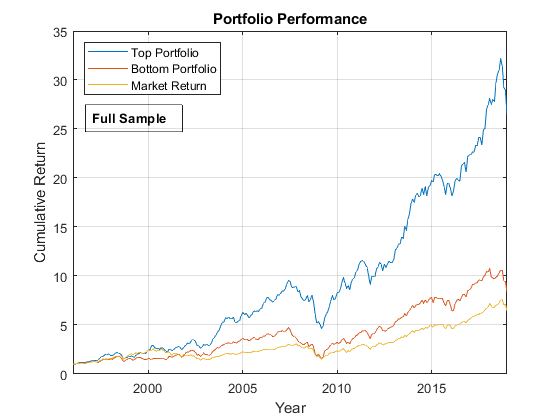

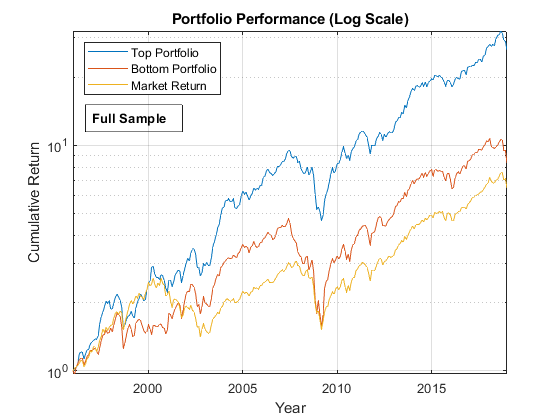

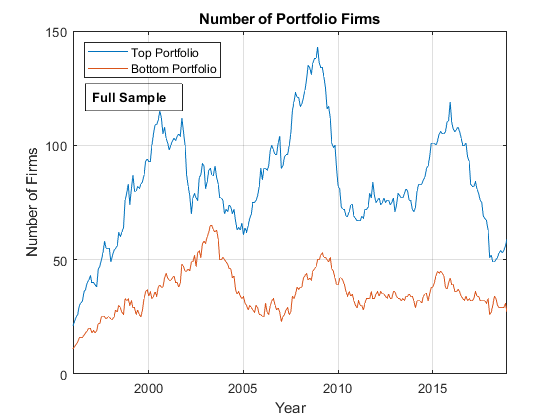

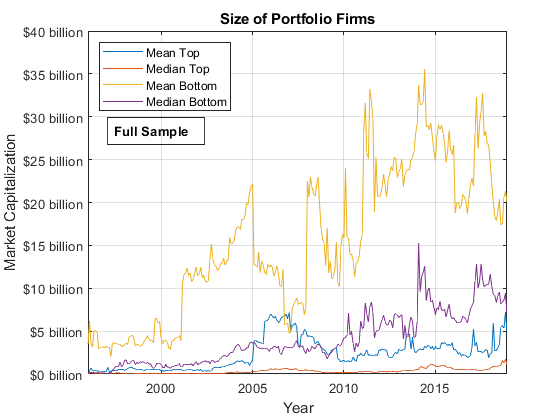

perf_top = 7×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    0.0051845    0.0013728     3.7765    0.00019576
    MKTRF            0.82956     0.036667     22.624     3.375e-64
    SMB              0.73483     0.047466     15.481    4.3055e-39
    HML              0.17209     0.062506     2.7531     0.0063045
    UMD             -0.14164     0.027798    -5.0952    6.5667e-07
    RMW             0.081355     0.066462     1.2241       0.22199
    CMA              0.12581     0.085083     1.4787        0.1404


perf_bottom = 7×4 table
                    Estimate        SE          tStat        pValue  
                   __________    _________    _________    __________

    (Intercept)    6.3091e-06    0.0012994    0.0048553       0.99613
    MKTRF              1.0677     0.034707       30.764    4.4251e-90
    SMB               0.58604     0.044928       13.044    1.8253e-30
    HML               0.38751     0.059165       6.5496    2.9171e-10
    UMD              -0.34751     0.026312      -13.207    4.9052e-31
    RMW               0.41697      0.06291       6.6281    1.8506e-10
    CMA             -0.081299     0.080535      -1.0095       0.31364


top_stat = 1×5 table
      Mean      Volatility    MaxDrawdown    SharpeRatio    InformationRatio
    ________    __________    ___________    ___________    ________________

    0.013292     0.052053      -0.18692        0.76362          0.84609     


bottom_stat = 1×5 table
      Mean       Volatility    MaxDrawdown    SharpeRatio    InformationRatio
    _________    __________    ___________    ___________    ________________

    0.0094978     0.05948       -0.25539        0.44752         0.0010878    


time_series = 276×21 table
      Month      Time     TopReturn     BottomReturn    MarketReturn    TopObs    BottomObs    TopExcess     BottomExcess     MKTRF       SMB        HML        UMD        RMW        CMA         LIQ          Rf      MeanSizeTop    MedianSizeTop    MeanSizeBottom    MedianSizeBottom
    _________    ____    ___________    ____________    ____________    ______    _________    __________    ____________    _______    _______    

plot_performance =   3×1 Line array:

  Line    (Top Portfolio)
  Line    (Bottom Portfolio)
  Line    (Market Return)


plot_performance_log =   3×1 Line array:

  Line    (Top Portfolio)
  Line    (Bottom Portfolio)
  Line    (Market Return)


size_plot =   2×1 Line array:

  Line    (Top Portfolio)
  Line    (Bottom Portfolio)


plot_obs =   4×1 Line array:

  Line    (Mean Top)
  Line    (Median Top)
  Line    (Mean Bottom)
  Line    (Median Bottom)


[perf_top,perf_bottom,top_stat,bottom_stat,time_series,plot_performance,plot_performance_log,size_plot,plot_obs]...
    = PortfolioBacktest(data,firm_size,1996,2018,24,5,15,8,1,IndexVariables,TopPerfModel,BottomPerfModel)

%toc